Abdullah Ahmed

aa09303

**Task 1)**

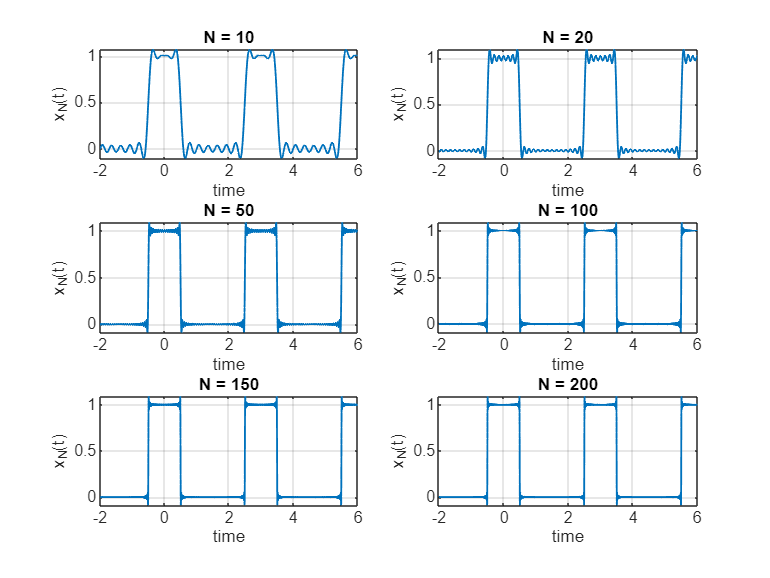

clc; clear; close all

% Define N values to plot
N_values = [10, 20, 50, 100, 150, 200];


a0 = 1/3;
T0 = 3;
omg0 = 2*pi/T0;


figure;
for i = 1:length(N_values)

    N = N_values(i);
    k = 1:N;
    t = -2:1/N/10:6;
    ak = 2*sin(pi*k/3)./(pi*k);
    xtN = a0;

    for kk = 1:N
        xtN = xtN + ak(kk) * cos(kk * omg0 * t);
    end
    
    subplot(3, 2, i);
    plot(t, xtN, 'linewidth', 1);
    grid on;
    xlabel('time');
    ylabel('x_N(t)');
    title(['N = ', num2str(N)]);
end

**Task 2)**

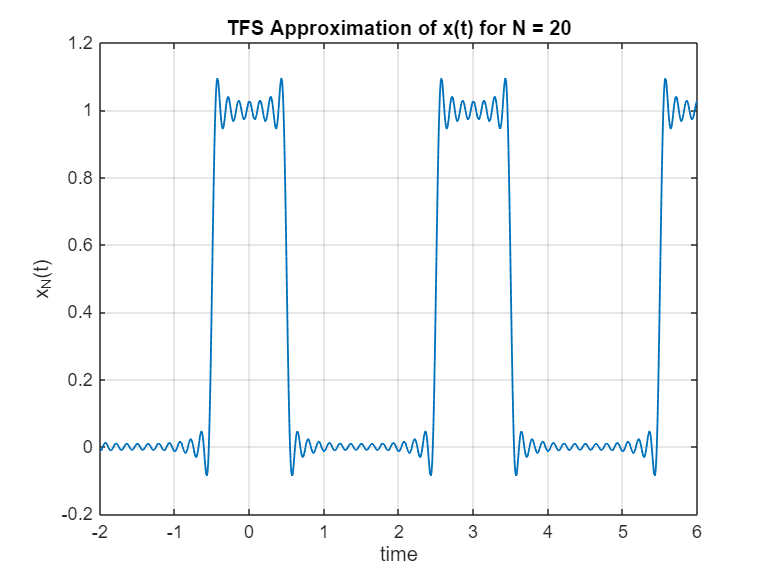

clc; clear; close all

% Given parameters
N = 20;
a0 = 1/3;
T0 = 3;
omg0 = 2*pi/T0;

t = -2:1/N/10:6;
k = 1:N;
ak = 2*sin(pi*k/3)./(pi*k);

dk = abs(ak);
theta_k = zeros(size(ak));
theta_k(ak < 0) = pi;

xtN = a0;
for kk = 1:N
    xtN = xtN + dk(kk) * cos(kk * omg0 * t - theta_k(kk));
end

% Plot the result
figure;
plot(t, xtN, 'linewidth', 1);
grid on;
xlabel('time');
ylabel('x_N(t)');
title('TFS Approximation of x(t) for N = 20');

**Comments:**

**This is giving the exact same result which means**

**Task 3)**

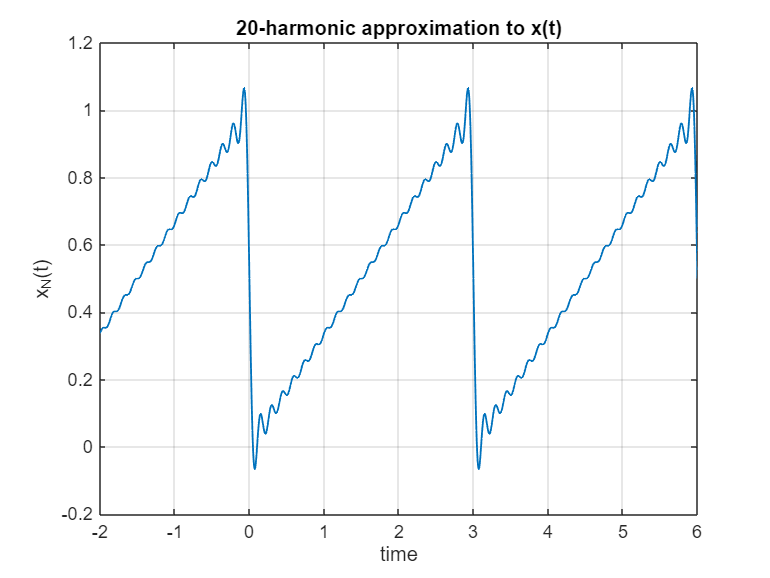

clc; clear; close all

a = 1;
T0 = 3;
omg0 = 2 * pi / T0;
N = 20;
t = -2:1/N/10:6;

a0 = a / 2;
k = 1:N;
ak = 2 * a * ((sin(2 * pi * k) ./ (2 * pi * k)) + (cos(2 * pi * k) - 1) ./ (4 * pi^2 * k.^2));
bk = 2 * a * ((sin(2 * pi * k) ./ (4 * pi^2 * k.^2)) - (cos(2 * pi * k) ./ (2 * pi * k)));


xtN = a0 * ones(size(t));
for kk = 1:N
    xtN = xtN + ak(kk) * cos(kk * omg0 * t) + bk(kk) * sin(kk * omg0 * t);
end

% Plot x_N(t) for N = 20
figure;
plot(t, xtN, 'linewidth', 1);
grid on;
xlabel('time');
ylabel('x_N(t)');
title('20-harmonic approximation to x(t)');

**Task 4)**

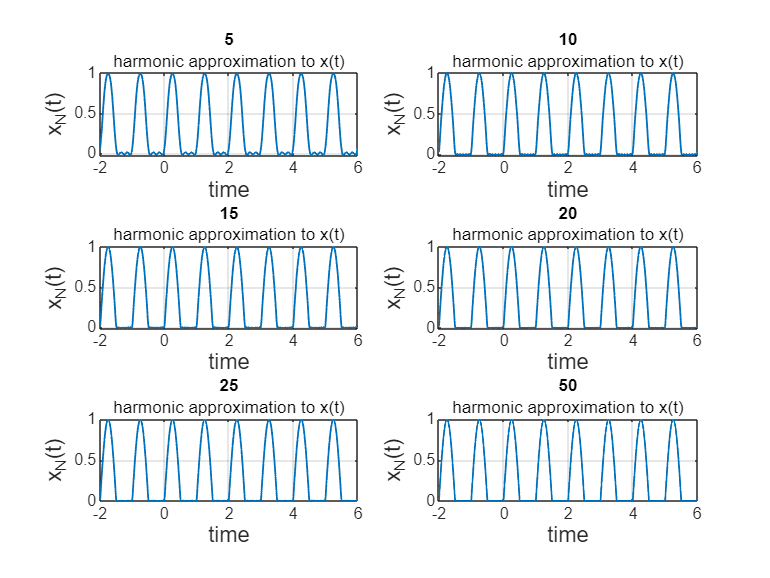

clc; clear; close all;

% Set the DC term "a0".
a0 = 1/pi;
% Define number of terms
N_values = [5, 10, 15, 20, 25, 50];

% Create a vector of time instants


T0 = 1;
omg0 = 2*pi/T0;

figure;

for i = 1:length(N_values)
    N = N_values(i);
    t = -2:1/N/10:6;
    k = 1:N;
    ak = zeros(size(k));
    even_k = mod(k,2) == 0;
    ak(even_k) = -2 ./ (pi * (k(even_k).^2 - 1));
    bk = (k == 1) *0.5; 
    
    xtN = a0;
    for kk = 1:N
        xtN = xtN + ak(kk) * cos(kk * omg0 * t) + bk(kk) * sin(kk * omg0 * t);
    end
    
    subplot(3,2,i);
    plot(t, xtN, 'linewidth', 1);
    grid on;
    xlabel('time', 'FontSize', 12);
    ylabel('x_N(t)', 'FontSize', 12);
    title(N, 'harmonic approximation to x(t)');
end

**Task 6)**